initSim

Cbase1v = 0.0150

l_f = 0.0265

r_f = 0.0063

SCR_grid = 10

z_grid = 0.1000

r_grid = 0.0196

x_grid = 0.0981

l_grid = 3.1213e-04

R_grid = 0.0041

L_grid = 6.6046e-05

R_mv = 0.6000

L_mv = 0.0034

x_mv_tot = 113.2518

x_hv_tot = 18.8496

r_mv_tot = 0.0912

r_hv_tot = 0.0013

ans = 1.4293e+03

k_p_p_vsm = 0.6000

k_p_q_vsm = -0.0500

k_d_vsm = 70

H_vsm = 3

ki_q = 314.1593

V_dc_base = 1.1268e+03

V_dc = 1.1268e+03

C_dc = 0.0236

ans = 1.5708

I_dc_base = 1.3312e+03

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


L_f = l_f*Lbase1v

L_f = 1.7849e-05

R_f = r_f*Zbase1v

R_f = 0.0013

C_f = 0.0757204*Cbase1v

C_f = 0.0011

% plant
    
G_plant = 1/(s*L_f+R_f)

G_plant =
 
            1
  ----------------------
  1.785e-05 s + 0.001333
 
Continuous-time transfer function.
Model Properties




f_sw = 5000

f_sw = 5000

omega_c = f_sw/10*2*pi

omega_c = 3.1416e+03

f_c = omega_c/(2*pi)

f_c = 500.0000

Tau_cc = 1/f_c

Tau_cc = 0.0020


Kp_cc = L_f/Tau_cc%

Kp_cc = 0.0089

Ki_cc =  R_f/Tau_cc %

Ki_cc = 0.6665

% G_cc = Kp_cc * (1+s*Ki_cc)/(s*Ki_cc)
G_cc = Kp_cc + Ki_cc/s

G_cc =
 
  0.008924 s + 0.6665
  -------------------
           s
 
Continuous-time transfer function.
Model Properties



v_od = 1;
v_od_m = v_od

v_od_m = 1



i_fd = 0;
i_fd_m = i_fd;
i_fd_ref = 1;
i_fq = 0;
i_fq_m = i_fq;

e_fd = i_fd_ref-i_fd_m;

omega = omega_nom/omega_nom

omega = 1



v_td = e_fd*G_cc-omega*L_f*i_fq_m-v_od_m;

i_fd = (v_td - v_od)*G_plant;

G_openl = G_cc*G_plant

G_openl =
 
     0.008924 s + 0.6665
  --------------------------
  1.785e-05 s^2 + 0.001333 s
 
Continuous-time transfer function.
Model Properties


G_cl = G_openl/(1+G_openl)

G_cl =
 
          1.593e-07 s^3 + 2.379e-05 s^2 + 0.0008886 s
  -----------------------------------------------------------
  3.186e-10 s^4 + 2.069e-07 s^3 + 2.557e-05 s^2 + 0.0008886 s
 
Continuous-time transfer function.
Model Properties


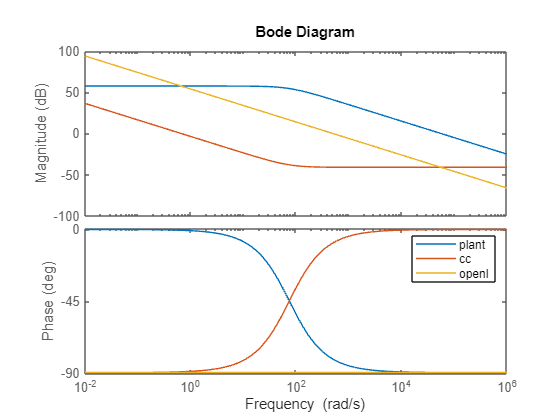


bode(G_plant,G_cc,G_openl,{10e-3,10e5})
legend('plant', 'cc','openl')

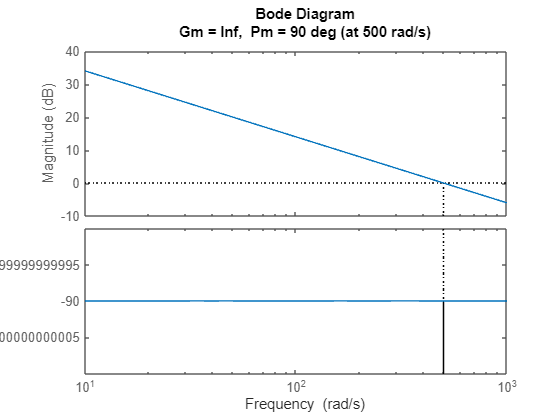



margin(G_openl)

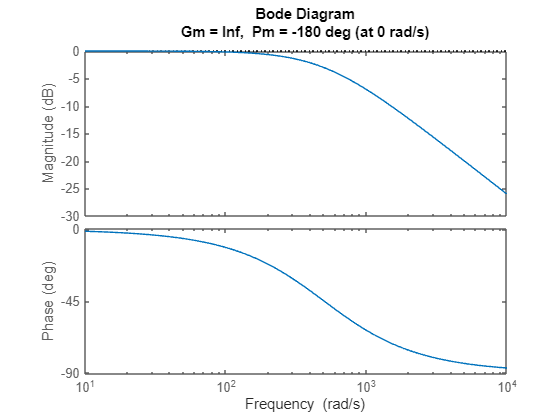

margin(G_cl)

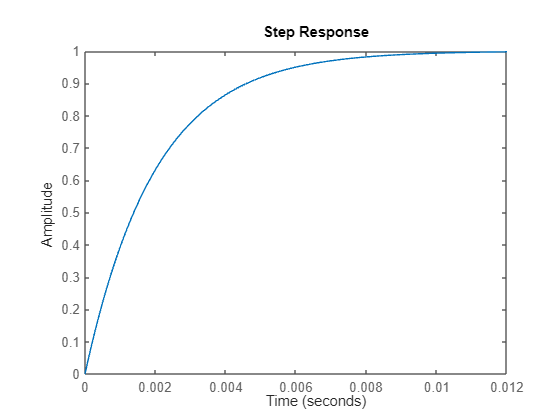

step(G_cl)

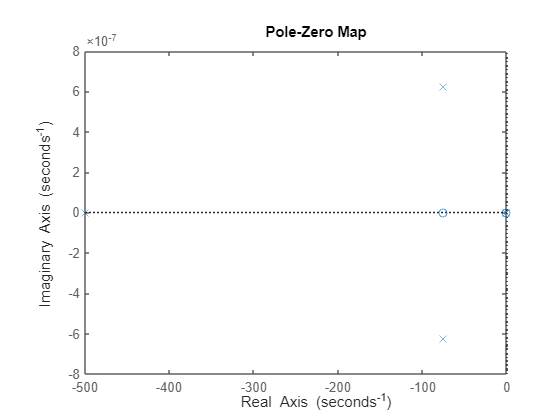

pzmap(G_cl)

Kp_vc = 0.03 %0.05%1/Vbase_lv;

Kp_vc = 0.0300

Ki_vc = 0.3 %1/f_c%Kp_cc*omega*(100.*omega*l_f + 71.*r_f)/(71.*omega*l_f - 100.*r_f); 

Ki_vc = 0.3000


% G_cc = Kp_cc * (1+s*Ki_cc)/(s*Ki_cc)
G_vc = Kp_vc + Ki_vc/s

G_vc =
 
  0.03 s + 0.3
  ------------
       s
 
Continuous-time transfer function.
Model Properties



G_openl = G_vc*G_cc*G_plant

G_openl =
 
  0.0002677 s^2 + 0.02267 s + 0.2
  -------------------------------
   1.785e-05 s^3 + 0.001333 s^2
 
Continuous-time transfer function.
Model Properties


G_cl = G_openl/(1+G_openl)

G_cl =
 
          4.779e-09 s^5 + 7.616e-07 s^4 + 3.379e-05 s^3 + 0.0002666 s^2
  -----------------------------------------------------------------------------
  3.186e-10 s^6 + 5.237e-08 s^5 + 2.539e-06 s^4 + 3.379e-05 s^3 + 0.0002666 s^2
 
Continuous-time transfer function.
Model Properties


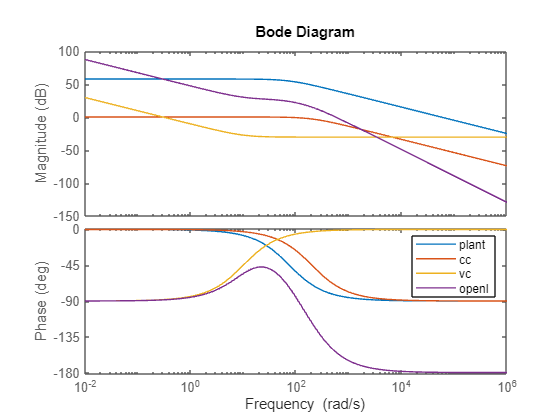


bode(G_plant,G_cc,G_vc,G_openl,{10e-3,10e5})
legend('plant', 'cc','vc','openl')

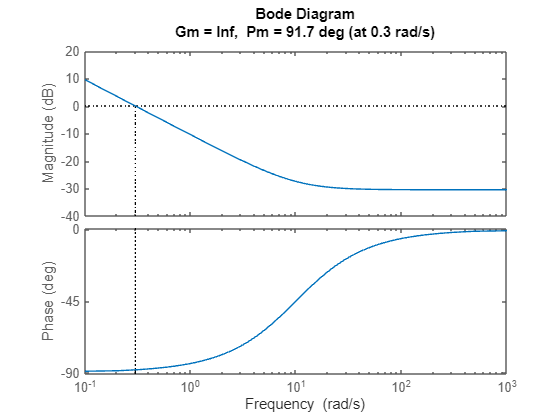


margin(G_vc)

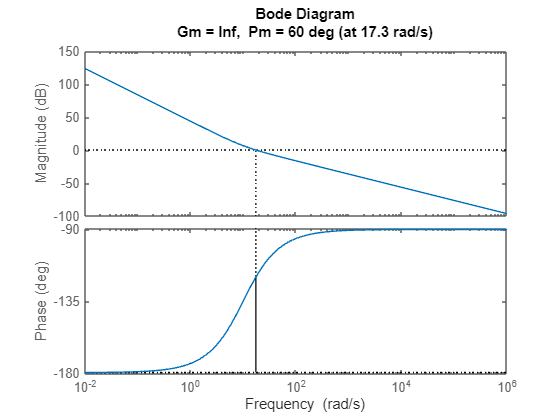

margin(G_openl,{10e-3,10e5})

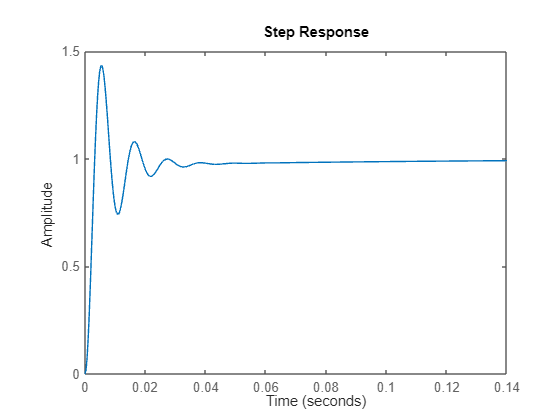


step(G_cl)

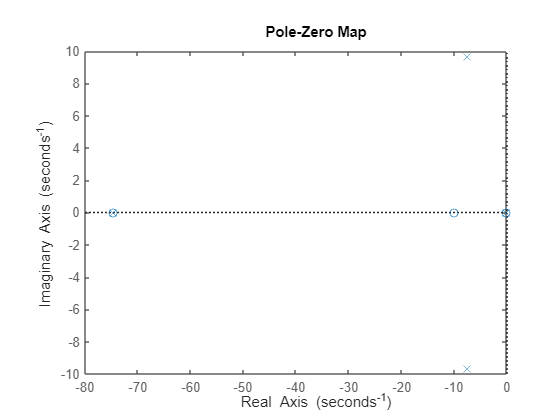

pzmap(G_cl)



asind((1-200*Tau_cc)/(1+200*Tau_cc))

ans = 54.9032

sqrt(Ki_vc*1/Tau_cc)

ans = 632.4555

ans*0.0757204

ans = 47.8898

% droop control

% (wmeas-wref)/(Pref-Pmeas) = kp_p

kp_p = (0.95-1)/(0.5-1)%0.05

kp_p = 0.1000


% (vmeas-vref)/(Qref-Qmeas) = -kp_q
kp_q = (0.9-1)/(0-0.5)

kp_q = 0.2000

(5+0.4/s)/(1-5+0.4/s)

ans =
 
  -5 s^2 - 0.4 s
  --------------
  4 s^2 - 0.4 s
 
Continuous-time transfer function.
Model Properties


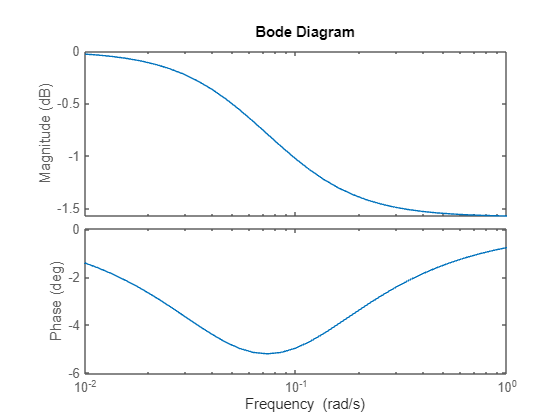


bode((5+0.4/s)/(1+5+0.4/s))

c_f=0.07

c_f = 0.0700

H=omega_c/2

H = 1.5708e+03

tau_dcc = 2*L_f/3*Sbase1/Vbase_lv^2

tau_dcc = 5.6235e-05

G_dc = -(2/C_f)*(tau_dcc*s+1)/s

G_dc =
 
  -0.09874 s - 1756
  -----------------
          s
 
Continuous-time transfer function.
Model Properties


G_cc = 1/(0.005*s+1)

G_cc =
 
       1
  -----------
  0.005 s + 1
 
Continuous-time transfer function.
Model Properties


K_v =C_f/2*H/s

K_v =
 
  0.8946
  ------
    s
 
Continuous-time transfer function.
Model Properties


loop_gain = K_v*G_cc*G_dc

loop_gain =
 
  -0.08833 s - 1571
  -----------------
   0.005 s^3 + s^2
 
Continuous-time transfer function.
Model Properties


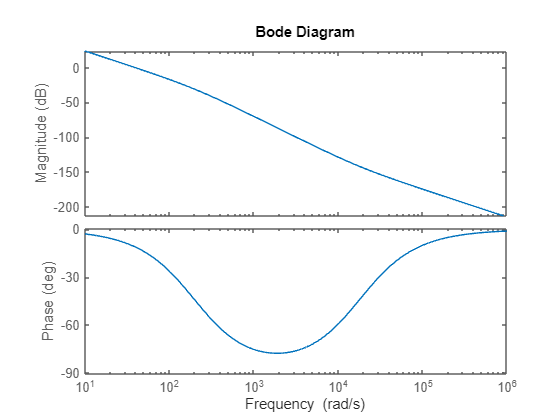

bode(loop_gain)

margin(H)
loop_gain/(1-loop_gain)

ans =
 
         -0.0004417 s^4 - 7.942 s^3 - 1571 s^2
  ---------------------------------------------------
  2.5e-05 s^6 + 0.01 s^5 + s^4 + 7.942 s^3 + 1571 s^2
 
Continuous-time transfer function.
Model Properties


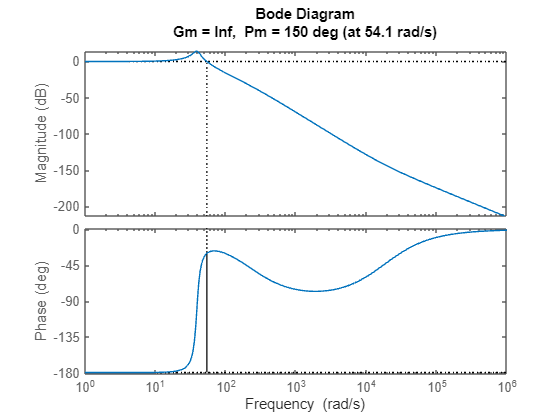

margin(loop_gain/(1-loop_gain))



1/0.005*2*pi

ans = 1.2566e+03